# Taller I - Parcial 2 

## Laura gutiérrez Arias y David Londoño Escandón

clc
clear all
close all
addpath('/home/laura/Documents/MATLAB/')

### Modelo Cinemático Directo

#### Matriz DH

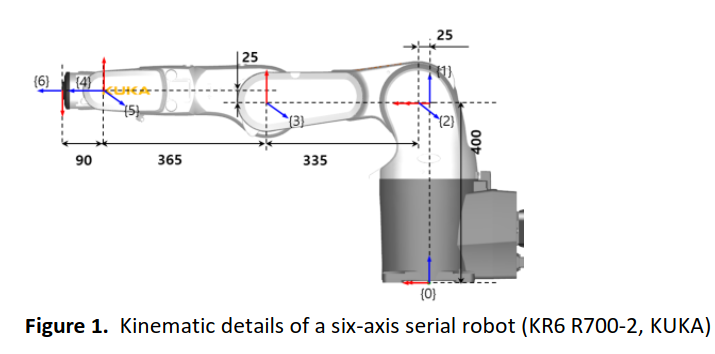

aij = [0 25 335 25 0 0]; 
alphaij = [0 -pi()/2 0 -pi()/2 pi()/2 -pi()/2];
sj = [400 0 0 365 0 90]; 
thetaj = [0 0 -90 0 0 180];
DH = [aij', alphaij', sj', deg2rad(thetaj)']

DH =          0         0  400.0000         0
   25.0000   -1.5708         0         0
  335.0000         0         0   -1.5708
   25.0000   -1.5708  365.0000         0
         0    1.5708         0         0
         0   -1.5708   90.0000    3.1416



frame=size(DH,1);

#### Transformada DH

for i=1:frame
    T_ij(:,:,i)=T_DH(DH(i,1),DH(i,2),DH(i,3),DH(i,4)); %Saca todos los frames respecto a un marco local
end
T(:,:,1)=T_ij(:,:,1);
for i=1:frame-1
    T(:,:,i+1)=T(:,:,i)*T_ij(:,:,i+1); % Transformacones de traslación y rotación (premult)
end
T

T = T(:,:,1) =

     1     0     0     0
     0     1     0     0
     0     0     1   400
     0     0     0     1


T(:,:,2) =

    1.0000         0         0   25.0000
         0    0.0000    1.0000         0
         0   -1.0000    0.0000  400.0000
         0         0         0    1.0000


T(:,:,3) =

    0.0000    1.0000         0  360.0000
   -0.0000    0.0000    1.0000         0
    1.0000   -0.0000    0.0000  400.0000
         0         0         0    1.0000


T(:,:,4) =

    0.0000    0.0000    1.0000  725.0000
   -0.0000   -1.0000    0.0000    0.0000
    1.0000   -0.0000   -0.0000  425.0000
         0         0         0    1.0000


T(:,:,5) =

    0.0000    1.0000         0  725.0000
   -0.0000         0    1.0000    0.0000
    1.0000   -0.0000    0.0000  425.0000
         0         0         0    1.0000


T(:,:,6) =

   -0.0000   -0.0000    1.0000  815.0000
   -0.0000    1.0000    0.0000    0.0000
   -1.0000   -0.0000   -0.0000  425.0000
         0         0         0    1

#### Gráfica

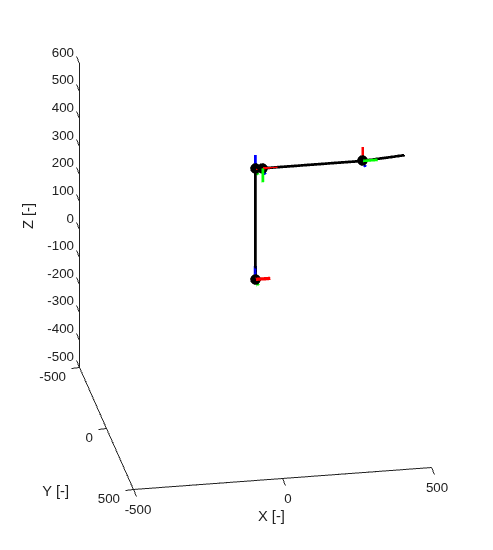

% Define the Fixed Frame
hf=figure(1);
set(hf,'position',[445   275   563   628])
% Unit vectors scale factor(visual)
L=50;
h_ejexF=plot3([0 L],[0 0],[0 0],'r','linewidth',2.5);
hold on
h_ejeyF=plot3([0 0],[0 L],[0 0],'g','linewidth',2.5);
hold on
h_ejezF=plot3([0 0],[0 0],[0 L],'b','linewidth',2.5);
hold on
axis equal
axis([-500 500 -500 500 -500 600])
xlabel('X [-]')
ylabel('Y [-]')
zlabel('Z [-]')
view(-27,-37)
% Mobile Coordinate System Based on DoF
for i=1:frame
    h_ejexM(i,1)=plot3([0 0],[0 0],[0 0],'r','linewidth',2);
    hold on
    h_ejeyM(i,1)=plot3([0 0],[0 0],[0 0],'g','linewidth',2);
    hold on
    h_ejezM(i,1)=plot3([0 0],[0 0],[0 0],'b','linewidth',2);
end
% Points Matrix on {j}
Mp=[0,0,0,1;
    L,0,0,1;
    0,L,0,1;
    0,0,L,1];
% Points Matrix on {0}
for k=1:frame
    for i=1:4
        Mp_T(i,:,k)=(T(:,:,k)*Mp(i,:)')'; % MARCO GLOBAL
    end
end
% Plot each Coordinate System in the Global Frame
for k=1:frame
    set(h_ejexM(k,1),'xdata',[Mp_T(1,1,k) Mp_T(2,1,k)],...
        'ydata',[Mp_T(1,2,k) Mp_T(2,2,k)],...
        'zdata',[Mp_T(1,3,k) Mp_T(2,3,k)])
    set(h_ejeyM(k,1),'xdata',[Mp_T(1,1,k) Mp_T(3,1,k)],...
        'ydata',[Mp_T(1,2,k) Mp_T(3,2,k)],...
        'zdata',[Mp_T(1,3,k) Mp_T(3,3,k)])
    set(h_ejezM(k,1),'xdata',[Mp_T(1,1,k) Mp_T(4,1,k)],...
        'ydata',[Mp_T(1,2,k) Mp_T(4,2,k)],...
        'zdata',[Mp_T(1,3,k) Mp_T(4,3,k)])
end

% Extract Origins: [Base (0,0,0) -> Frame 1 -> Frame 2 -> ...]
P = [0 0 0; squeeze(T(1:3,4,:))']; 

% GRaph the links
plot3(P(:,1), P(:,2), P(:,3), 'k-o', 'LineWidth', 2, 'MarkerFaceColor', 'k');

#### Chequeo de Desacople

Verifico que parado en el origen del frame de la herramienta (frame 6), me devuelvo 90 unidades caminando en sentido *opuesto* al eje  a (el eje z de la herramienta, que apunta hacia afuera, en la dirección en que la herramienta se acerca a la pieza),  y debería llegar exactamente al punto donde están ubicados los orígenes de los frames 4 y 5, que es el centro de la muñeca  Pc�.

origen4 = T(1:3,4,4)

origen4 =   725.0000
    0.0000
  425.0000


origen5 = T(1:3,4,5)

origen5 =   725.0000
    0.0000
  425.0000



P_deseado = T(1:3,4,6);      % posición actual de la herramienta
R_deseado = T(1:3,1:3,6);    % Orientación ejes herramienta
a_vec = R_deseado(:,3);      % tercera columna = vector de aproximación a
dist_retr = sj(6);

Pc = P_deseado -sj(6)*a_vec

Pc =   725.0000
    0.0000
  425.0000


Verificamos que si son iguales entonces procedemos a utilizar la técnica del desacople. 

### Cinemática Inversa

Verificado que funciona el desacople, aplicamos: 

Planteamos el simbólico

function [SlnSet] = IK_trayectoria(Q, S, A67, aij, alphaij, sj)
% Q, S, A67: matrices de nx3 donde n es el número de puntos de la
% trayectoria 
% aij, alphaij, sj: son los vectores del DH original
    n = size(Q,1); 
    SlnSet = NaN(n, 6, 8);

    syms th1 th2 th3 th4 th5 th6 real
    syms px py pz real
    syms wx wy wz ux uy uz real
    syms qx qy qz real

    thetaj_syms = [th1 th2 th3 th4 th5 th6];
    DH_syms = [aij', alphaij', sj', thetaj_syms']
    DH = [aij', alphaij', sj', zeros(6,1)]; % numérica pero sin theta

    frame = size(DH_syms, 1)

    for i=1:frame
        T_ij_syms(:,:,i)=T_DH(DH_syms(i,1),DH_syms(i,2),DH_syms(i,3),DH_syms(i,4)); 
    end
    T_syms(:,:,1)=T_ij_syms(:,:,1);
    for i=1:frame-1
        T_syms(:,:,i+1)=T_syms(:,:,i)*T_ij_syms(:,:,i+1); 
    end
    T_syms

Luego Creamos las ecuciones RHS y LHS


    Pc = [px,py,pz,1]'

    RHS = simplify(expand(inv(T_ij_syms(:,:,1))*Pc))
    RHS(1) = RHS(1) - DH(2,1)

    Pc3 = [DH_syms(4, 1);
            -DH_syms(4, 3)*sin(DH_syms(4,2));
            DH_syms(4, 3)*cos(DH_syms(4,2))] % Punto de la muñeca (4) visto desde 3

    LHS = simplify(expand(T_ij_syms(:, :, 2)*T_ij_syms(:, :, 3)*[Pc3;1]))
    LHS(1) = LHS(1) - DH(2,1)

Comenzamos a hayar las soluciones a partir de esas fórmulas

    %% ---- THETA1 (2 ramas) ----
    th1_a = atan2(Pc(2), Pc(1));
    th1_b = th1_a + pi;

    %% ---- THETA3 (suma de cuadrados) ----
    LHS_ss = expand(LHS(1)^2 + LHS(3)^2);   
    RHS_ss = expand(RHS(1)^2 + RHS(3)^2);   

    LHS_ss = simplify(LHS_ss);   % la dependencia de th2 debe cancelarse aquí

    syms cos_th3 sin_th3 real
    LHS_ss_mod = subs(LHS_ss, [cos(th3), sin(th3)], [cos_th3, sin_th3]);
    coeffs3 = jacobian(LHS_ss_mod, [cos_th3, sin_th3]); % Saca la matriz de derivadas parciales para aislar A y B

    A = coeffs3(1);
    B = coeffs3(2);
    LHS_ss_indep = simplify(LHS_ss_mod - dot(coeffs3, [cos_th3, sin_th3]));  % parte constante, sin th3 (C)

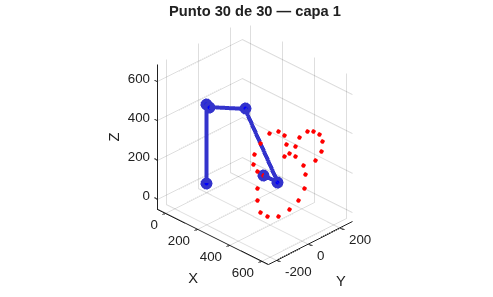

    D = simplify(LHS_ss_indep - RHS_ss);   % aquí sí entran px,py,pz (via RHS_ss)

    h = sqrt(A^2 + B^2); % Truco  auxiliar del triángulo para resolver
    alpha_aux = atan2(B, A);


    th3_a =  acos(-D/h) + alpha_aux;   % codo arriba
    th3_b = -acos(-D/h) + alpha_aux;   % codo abajo


    %% ---- THETA2 (sistema lineal) ----
    syms cos_th2 sin_th2 real

    eqs_lhs = [LHS(1); LHS(3)];
    eqs_lhs_mod = subs(eqs_lhs, [cos(th2), sin(th2)], [cos_th2, sin_th2]);
    Amat2 = jacobian(eqs_lhs_mod, [cos_th2, sin_th2]);   % matriz 2x2, en función de th3

    eqs_rhs = [RHS(1); RHS(3)];   % lado derecho, en función de th1, px,py,pz

    % Resuelve el sistema matricial por Cramer
    det_A2 = simplify(det(Amat2));
    cos_th2_sol = simplify((eqs_rhs(1)*Amat2(2,2) - eqs_rhs(2)*Amat2(1,2)) / det_A2);
    sin_th2_sol = simplify((Amat2(1,1)*eqs_rhs(2) - Amat2(2,1)*eqs_rhs(1)) / det_A2);

    th2_formula = atan2(sin_th2_sol, cos_th2_sol); 


    %% ---- THETA4, THETA5, THETA6 (orientación) ----
    R_f1 = T_ij_syms(1:3, 1:3, 1);
    R_12 = T_ij_syms(1:3, 1:3, 2);
    R_23 = T_ij_syms(1:3, 1:3, 3);
    R_f3 = R_f1*R_12*R_23;

    q_f6 = [qx; qy; qz]; 
    S_vec = [wx; wy; wz];  % 0S6 -> APROXIMACION (eje z herramienta)


    a67_vec = [ux; uy; uz];    % 0a67 -> segundo eje (deslizamiento/orientacion)
    n_vec   = cross(a67_vec, S_vec);   % tercer eje, completando la terna ortonormal

    R_deseado = [n_vec, a67_vec, S_vec];  

    Pc_sym = q_f6 - abs(DH(6,3))*S_vec;   % Pos deseada + |offset de muñeca a herramienta*VecAproximacion|

    R_36_lhs = simplify(R_f3.' * R_deseado);

    for k = 1:n
        % Sustituir qx,qy,qz,wx,wy,wz,ux,uy,uz por los del punto k,
        % y de ahi px,py,pz salen evaluados via Pc_sym (NO reasignando variables)
        subs_vars = [qx,qy,qz, wx,wy,wz, ux,uy,uz];
        subs_vals = [Q(k,1),Q(k,2),Q(k,3), S(k,1),S(k,2),S(k,3), A67(k,1),A67(k,2),A67(k,3)];

        Pc_num = double(subs(Pc_sym, subs_vars, subs_vals));

        subs_pos = [px,py,pz];
        vals_pos = Pc_num(:)';

        th1_vals = [double(subs(th1_a, subs_pos, vals_pos)), ...
            double(subs(th1_b, subs_pos, vals_pos))];
        th3_vals = [double(subs(th3_a, subs_pos, vals_pos)), ...
            double(subs(th3_b, subs_pos, vals_pos))];

        col = 0;
        for i1 = 1:2
            for i3 = 1:2
                th2_num = real(double(subs(th2_formula, [th1, th3, subs_pos], ...
                    [th1_vals(i1), th3_vals(i3), vals_pos])));

                R36_num = double(subs(R_36_lhs, [th1, th2, th3, subs_vars], ...
                    [th1_vals(i1), th2_num, th3_vals(i3), subs_vals]));

                th5_vals = [acos(R36_num(2,3)), -acos(R36_num(2,3))];
                for i5 = 1:2
                    s5 = sin(th5_vals(i5));
                    th6_num = atan2(-R36_num(2,2)/s5,  R36_num(2,1)/s5);
                    th4_num = atan2( R36_num(3,3)/s5, -R36_num(1,3)/s5);

                    col = col + 1;
                    SlnSet(k,:,col) = [th1_vals(i1); th2_num; th3_vals(i3); th4_num; th5_vals(i5); th6_num];
                end
            end
        end
    end
end



## Implementación de Código anterior como función

A partir del código base previamente mostrado, se convirtió en una función de manera que se pudiera calcular la cinemática Inversa de cada punto de la trayectoria. 

clc
clear all
close all
addpath('/home/laura/Documents/MATLAB/Parcial 2/')

aij = [0 25 335 25 0 0];
alphaij = [0 -pi/2 0 -pi/2 pi/2 -pi/2];
sj = [400 0 0 365 0 90];

coordenadas = [
    294.99  678.37;  % E1
    253.88  768.07;  % F1
    265.09  861.50;  % G1
    337.97  949.34;  % H1
    453.83  997.92;  % I1
    560.35  982.97;  % J1
    640.71  908.22;  % K1
    665.00  805.44;  % L1
    629.50  697.05;  % G
    700.00  700.00;  % H
    771.52  640.99;  % I
    769.65  736.30;  % J
    816.37  809.18;  % K
    917.28  837.21;  % L
    1000.00 800.00;  % M
    1074.26 734.43;  % N
    1109.77 652.20;  % O
    1091.08 562.50;  % P
    1016.33 495.23;  % Q
    868.70  504.57;  % R
    900.00  400.00;  % S
    881.78  263.50;  % T
    805.16  181.28;  % U
    694.90  130.82;  % V
    558.48  117.74;  % W
    425.80  164.46;  % Z
    336.10  250.42;  % A1
    296.86  386.84;  % B1
    300.00  500.00;  % C1
    371.61  611.09;  % D1


];


u = coordenadas(:,1);
v = coordenadas(:,2);

n = length(coordenadas);

 % Centrar
u = u - mean(u);              
v = v - mean(v);
escala = 250 / max(sqrt(u.^2+v.^2));   % ajusta el radio de la figura
u = u*escala;
v = v*escala;

% Ubicacion del plano en el workspace del robot 
P0  = [500, 0, 300];
e_u = [0, 1, 0]; % Y de la gráfica
e_v = [0, 0, 1]; % z de l agráfica
n_vec_plane = cross(e_u, e_v);

Q = P0 + u.*e_u + v.*e_v;     % 25x3, ya en el mundo del robot


% Orientación de la Herramienta
S_dir   = -n_vec_plane / norm(n_vec_plane);   % aproximacion: hacia el plano
A67_dir =  e_u / norm(e_u);                   % segundo eje de la terna

S   = repmat(S_dir,   n, 1);   % misma fila n veces bc no cambia
A67 = repmat(A67_dir, n, 1);

[SlnSet, SlnSetVer] = IK_try(Q, S, A67, aij, alphaij, sj);

#### Gráfica

capa = 1; 
guardar_video = false;
pause = 0.14;
animar_robot(SlnSetVer, capa, aij, alphaij, sj, guardar_video, pause)